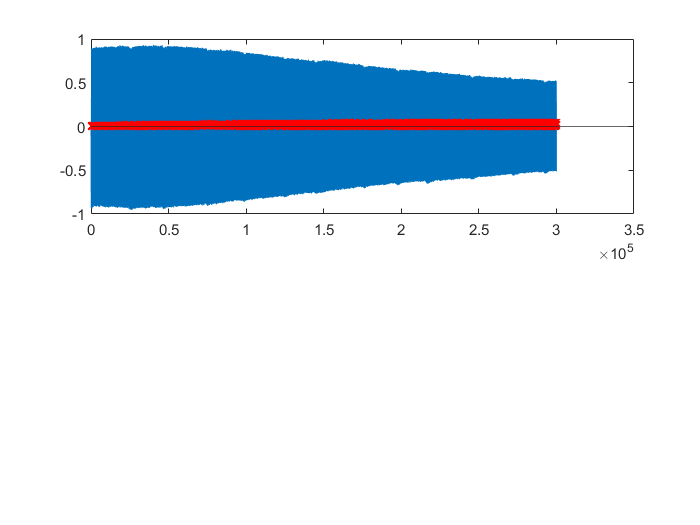

% function [I_spike_phase, II_spike_phase, III_spike_phase, I_spike, II_spike, III_spike] = spike_phase(stimulus, raster_data, fs, start_stim, stop_stim, stim_type, freq)

P_idx = 2;
resp = P(P_idx).raster(:,start_stim:stop_stim);
stim = P(P_idx).stim_ifb(1,start_stim:stop_stim);

order = 4;
[x,y] = butter(order, max_chirp_frq*2/(fs/2), 'low');
stim = filtfilt(x,y,stim);

mean_pos = mean(stim(1,:));
freq = P(P_idx).inc_frq_chirp_f;

locs = [];
zc = nan([1,length(stim)]);
for j = 2:length(stim)
    if (stim(1,j-1)<=mean_pos && stim(1,j)>=mean_pos && stim(1,j+1)>mean_pos)
        zc(j) = 1;
    end
end
locs = find(zc==1);

figure;
A1 =  subplot(2,1,1); plot(stim(1,:)); hold on; plot(locs, stim(1, locs), 'rx'); yline(mean_pos); hold off;

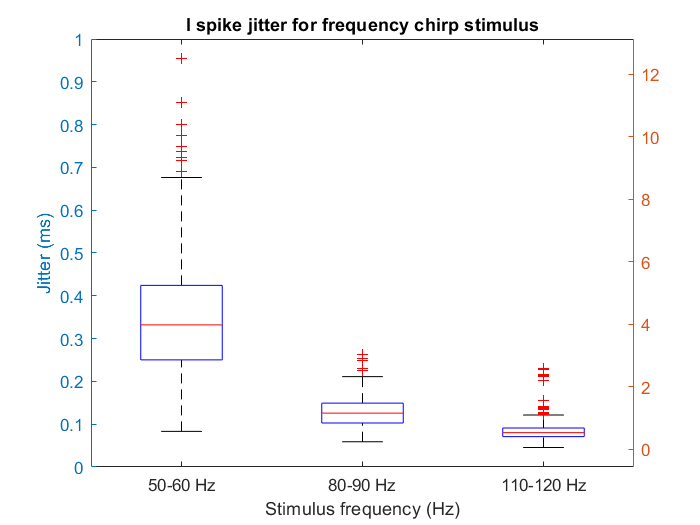


stim_clips = [];
resp_clips = [];
I_spike_phase = [];
II_spike_phase = [];
III_spike_phase = [];
I_spike = [];
II_spike = [];
III_spike = [];

spike_time_sd = [];


I = 1; II = 1; III=1;
for k= 2:length(locs)
    stim_clips = stim(1, locs(k-1):locs(k));
    resp_clips = resp(:, locs(k-1):locs(k));
    
    [row_ind,col_ind] = find(resp_clips == 1);
    
      
    [C, ia, ic] = unique(row_ind);
    ind = col_ind(ia);
    
%     figure;
%     plot(stim_clips); hold on; plot(ind, stim_clips(ind), 'rx');
    
    if length(col_ind)>=1
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(ind(1)));
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(k-1));
        I_spike_time = ind/fs;
        if length(ind) >=3
            spike_time_sd(I) = std(I_spike_time);
            I_spike(I) = freq(ind(1)+locs(k-1));%stim_freq(k-1);
            I=I+1;
        end
    end
    
    
    
    %     elseif stim_type == "amp"
    %
    %         stim_period = 1/freq;
    % %         stim_freq = 1 ./ (diff(locs) / fs);
    % %         stim_period = 1./stim_freq;
    %
    %         if length(ind)>=1
    %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period);
    %             I_spike(I) = max(stim_clips) - min(stim_clips);
    %             I=I+1;
    %         end
    %
    %
    %     end
end

figure;
yyaxis left; scatter(I_spike, spike_time_sd*1000, '.')
hold on;
ylabel('Jitter (ms)');
xlabel('Stimulus frequency (Hz)');


low_hz_ind = find(floor(I_spike)==60, 1,'first');
mid_hz_low = find(floor(I_spike)==80,1,'first');
mid_hz_high = find(floor(I_spike)==90,1,'first');
high_hz_ind = find(floor(I_spike)==110,1,'first');

jitter_1 = spike_time_sd(1:low_hz_ind);
jitter_2 = spike_time_sd(mid_hz_low:mid_hz_high);
jitter_3 = spike_time_sd(high_hz_ind:end);
jitter_groups = [jitter_1'; jitter_2'; jitter_3'];

g1 = repmat({'50-60 Hz'}, length(jitter_1),1);
g2 = repmat({'80-90 Hz'}, length(jitter_2),1);
g3 = repmat({'110-120 Hz'}, length(jitter_3),1);
g=[g1;g2;g3];

yyaxis right; boxplot(jitter_groups*1000, g)
% ylabel('I spike jitter (ms)');
title('I spike jitter for frequency chirp stimulus')